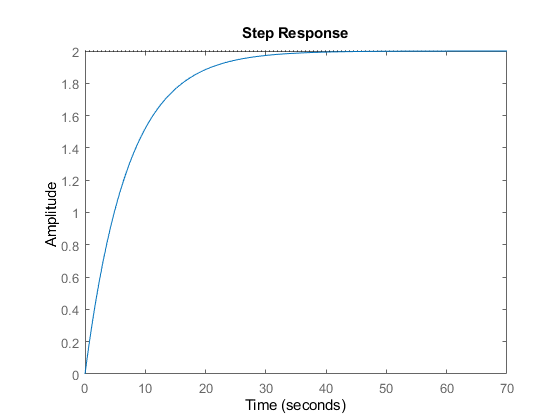

% clc; clear;
num = 2; den = [7 1]; roots = [-0.5 -0.5];

sys = tf(num, den);
Ts = 0.2;

[r0,r1,r_1] = controller(num,den,roots);

pid = tf([r1 r0 r_1],[1 0]);
uro = feedback(pid * sys, 1);
step(sys);

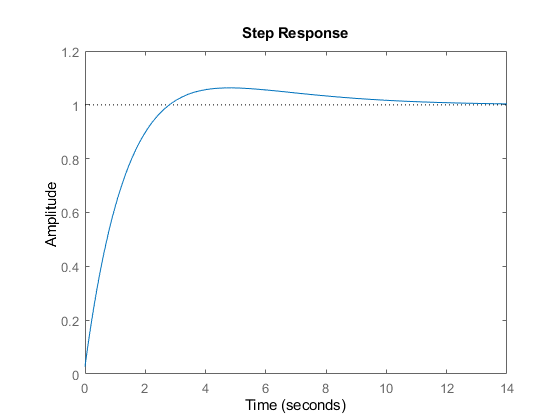

step(uro);

[q0,q1,q2] = pid2psd(r0,r1,r_1,Ts);

Podmienky ekvivalentnosti su splnene!


q0n = double(int16(((q0 + 50) * 100)));
q1n = double(uint16((q1 + 50) * 100));
q2n = double(uint16((q2 + 50) * 100));
m = modbus('tcpip','192.168.1.30',502);
write(m, 'holdingregs',5, Ts * 1000);
write(m, 'holdingregs',2, q0n);
write(m, 'holdingregs',3, q1n);
write(m, 'holdingregs',4, q2n);

clear m;